### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

### Calculate oxygen sensor lag for CTD alignment 

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')
% Casts 
cast01 = readSBScnv( 'ar0701001_hyst.cnv' );
cast02 = readSBScnv( 'ar0701002_hyst.cnv' );
cast03 = readSBScnv( 'ar0701003_hyst.cnv' );
cast04 = readSBScnv( 'ar0701004_hyst.cnv' );
cast05 = readSBScnv( 'ar0701005_hyst.cnv' );
cast06 = readSBScnv( 'ar0701006_hyst.cnv' );
cast07 = readSBScnv( 'ar0701007_hyst.cnv' );
cast08 = readSBScnv( 'ar0701008_hyst.cnv' );
cast09 = readSBScnv( 'ar0701009_hyst.cnv' );
cast10 = readSBScnv( 'ar0701010_hyst.cnv' );


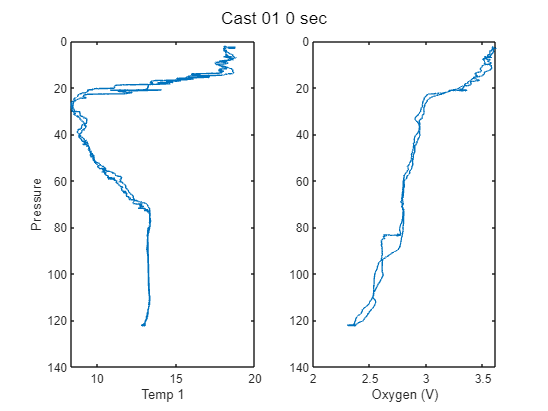

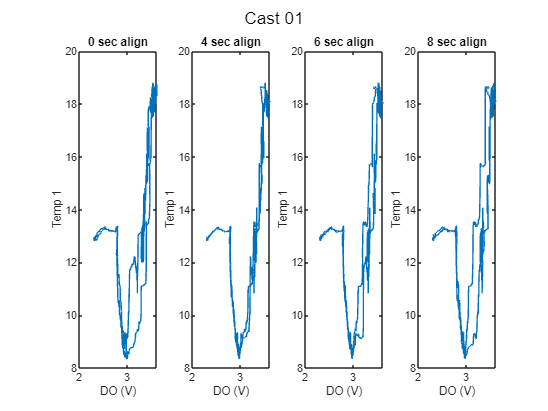

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;
cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

CTD_sen1 = 1; % Use primary or secondary CTD temp and sal
CTD_sen2 = 2; 

cast01 = align_CTD_by_sensor_KF(cast01,'Cast 01',a1,a2,a3,CTD_sen1);

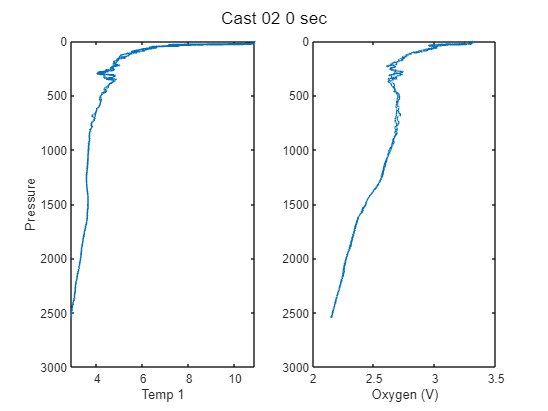

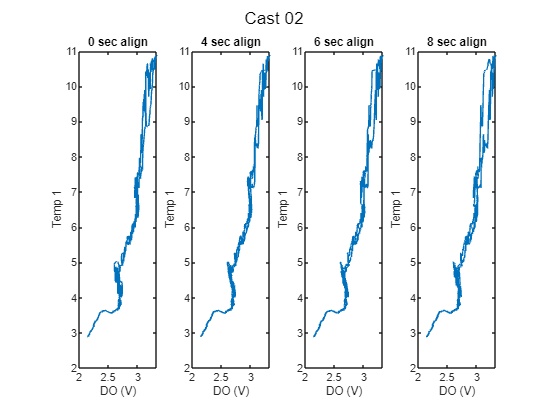

cast02 = align_CTD_by_sensor_KF(cast02,'Cast 02',a1,a2,a3,CTD_sen1);

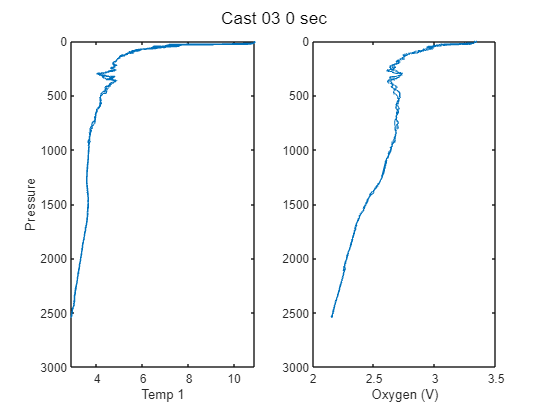

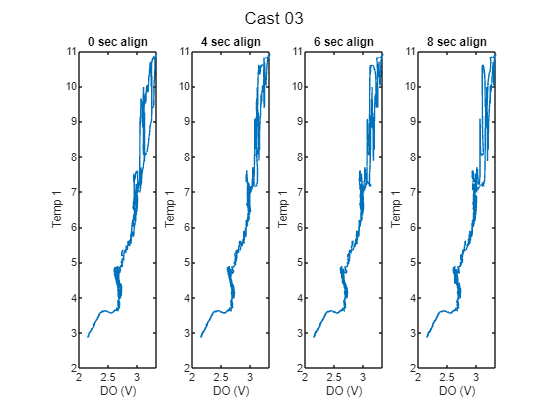

cast03 = align_CTD_by_sensor_KF(cast03,'Cast 03',a1,a2,a3,CTD_sen1);

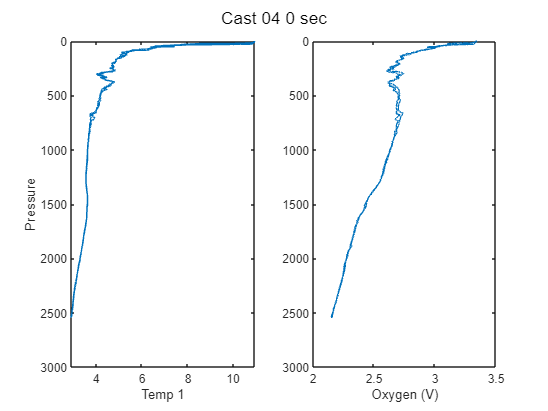

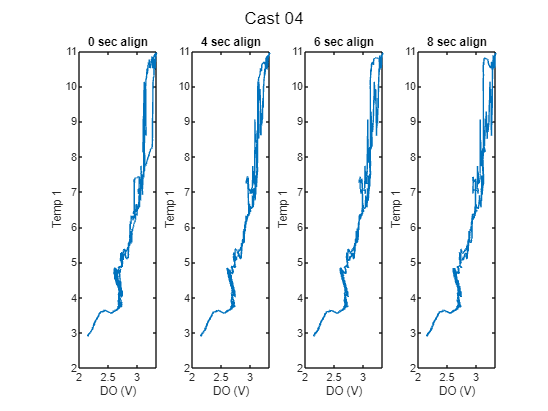

cast04 = align_CTD_by_sensor_KF(cast04,'Cast 04',a1,a2,a3,CTD_sen1);

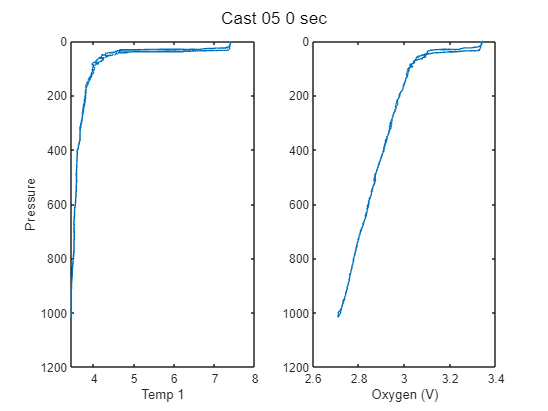

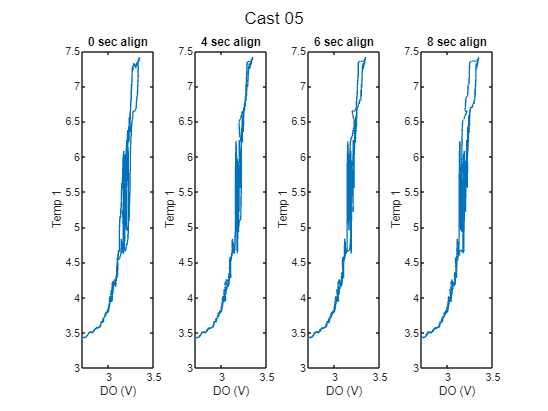

cast05 = align_CTD_by_sensor_KF(cast05,'Cast 05',a1,a2,a3,CTD_sen1);

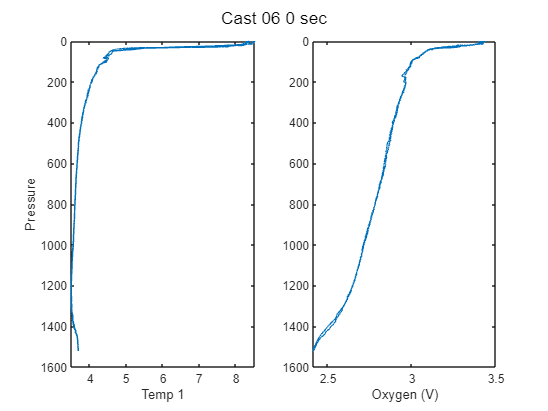

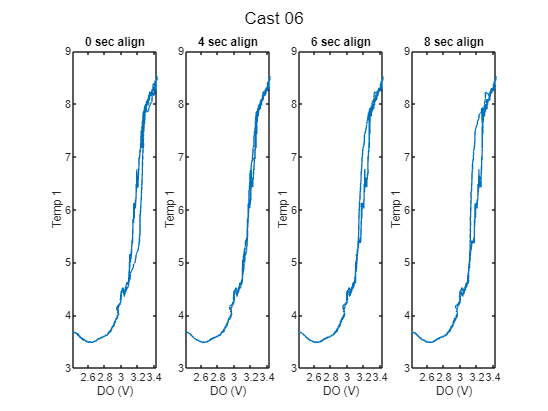

cast06 = align_CTD_by_sensor_KF(cast06,'Cast 06',a1,a2,a3,CTD_sen1);

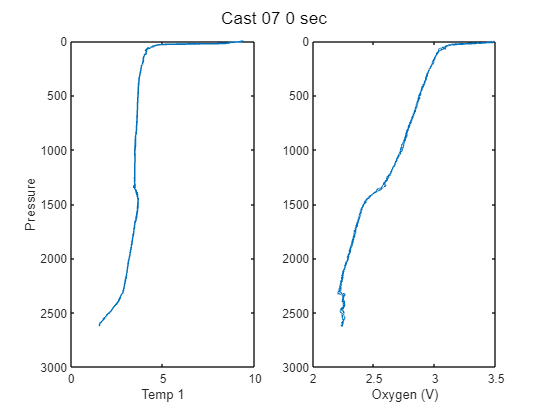

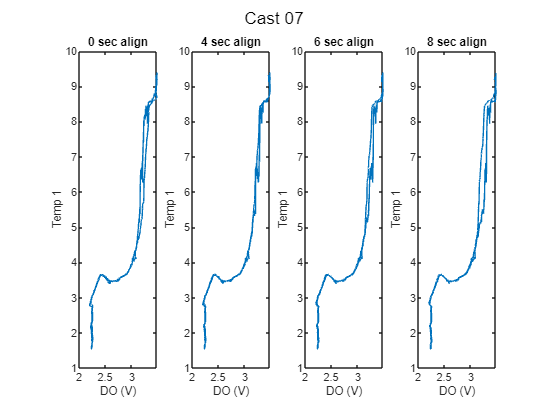

cast07 = align_CTD_by_sensor_KF(cast07,'Cast 07',a1,a2,a3,CTD_sen1);

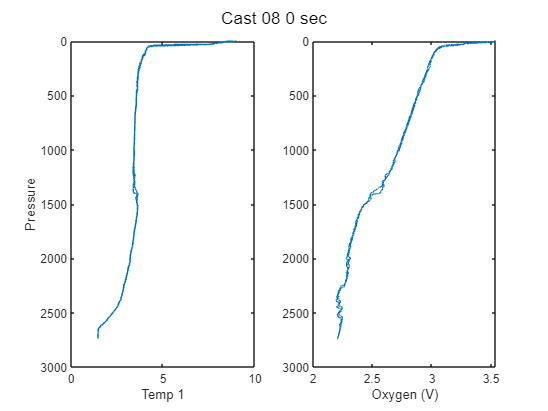

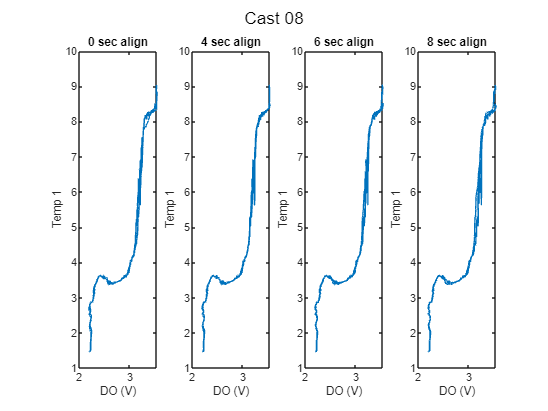

cast08 = align_CTD_by_sensor_KF(cast08,'Cast 08',a1,a2,a3,CTD_sen1);

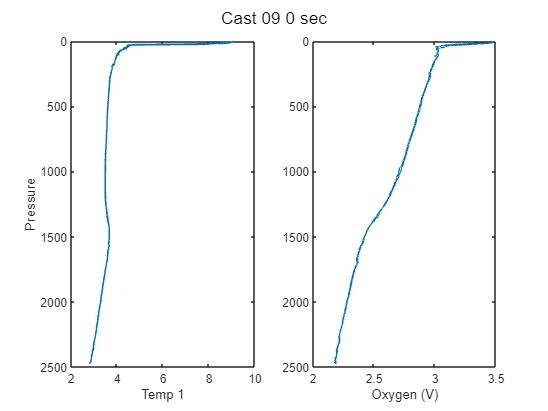

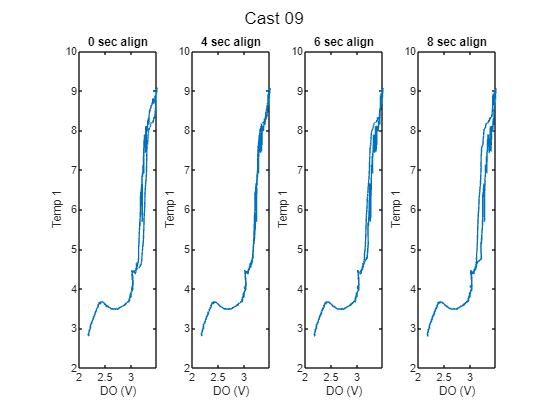

cast09 = align_CTD_by_sensor_KF(cast09,'Cast 09',a1,a2,a3,CTD_sen1);

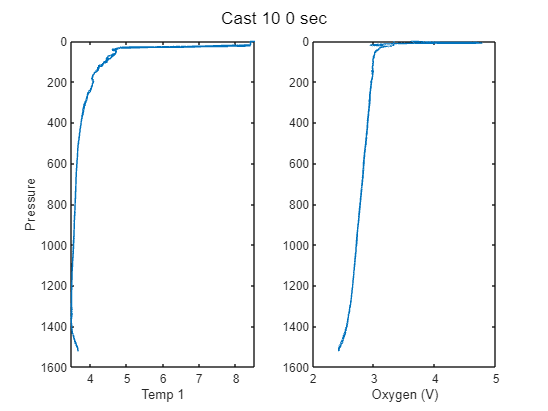

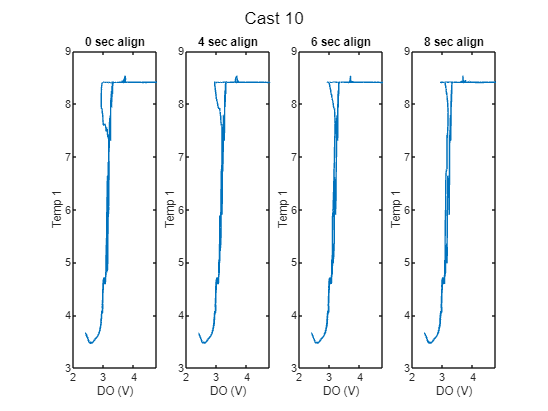

cast10 = align_CTD_by_sensor_KF(cast10,'Cast 10',a1,a2,a3,CTD_sen1);

clear cast*
% Pick align_sec
a1 = 4;
align_sec = a1; 

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 

% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year3')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')

btl = readtable('Irminger_Sea-03_AR7-01_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);

btlsum05 = combine_btl_files_woutCTDcal('ar0701005.csv',btlsum05);

btlsum06 = combine_btl_files_woutCTDcal('ar0701006.csv',btlsum06);

btlsum07 = combine_btl_files_woutCTDcal('ar0701007.csv',btlsum07);

btlsum08 = combine_btl_files_woutCTDcal('ar0701008.csv',btlsum08);

btlsum09 = combine_btl_files_woutCTDcal('ar0701009.csv',btlsum09);

btlsum10 = combine_btl_files_woutCTDcal('ar0701010.csv',btlsum10);


%% If get finalized finalsfrom Leah 
% btlsum02 = combine_btl_files('ar0701002.cbot_s','ar0701002.csv',btlsum02,CTD_sen1);
% btlsum03 = combine_btl_files('ar0701003.cbot_s','ar0701003.csv',btlsum03,CTD_sen1);
% btlsum04 = combine_btl_files('ar0701004.cbot_s','ar0701004.csv',btlsum04,CTD_sen1);
% btlsum05 = combine_btl_files('ar0701005.cbot_s','ar0701005.csv',btlsum05,CTD_sen1);
% btlsum06 = combine_btl_files('ar0701006.cbot_s','ar0701006.csv',btlsum06,CTD_sen1);
% btlsum07 = combine_btl_files('ar0701007.cbot_s','ar0701007.csv',btlsum07,CTD_sen1);
% btlsum09 = combine_btl_files('ar0701009.cbot_s','ar0701009.csv',btlsum09,CTD_sen1);

btlsum_yr3 = [btlsum05; btlsum06; btlsum07; btlsum08; btlsum09; btlsum10];
btlsum0 = btlsum_yr3; %

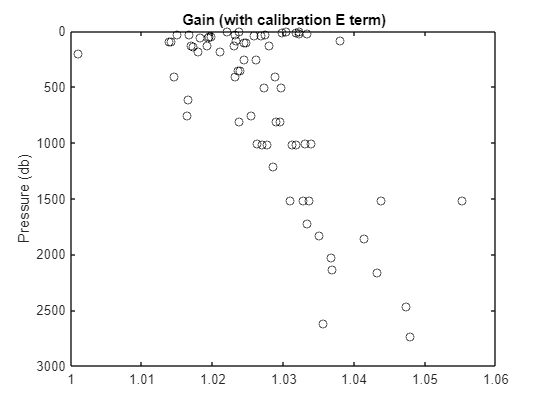

figure % Winkler/CTD Oxygen (without Leah calibrated Sal product)
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Same oxgen sensor whole cruise  
% Calibration standards from SBE xmlcon file 

cal.SOC = double(3.79510e-001);
cal.VOFFSET = double(-5.82400e-001);
cal.A = double(-4.14790e-003);
cal.B = double(2.08070e-004);
cal.C = double(-3.05950e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.16000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0338';
cal.OCALDATE = '16-Jan-16';

H = [-0.033, 5000, 1450]; % Default 

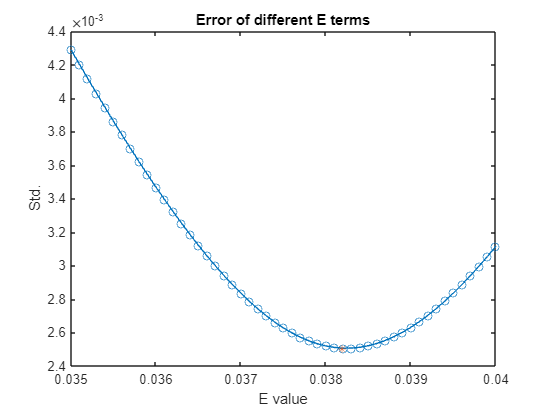

cal.E2 = 0.0382


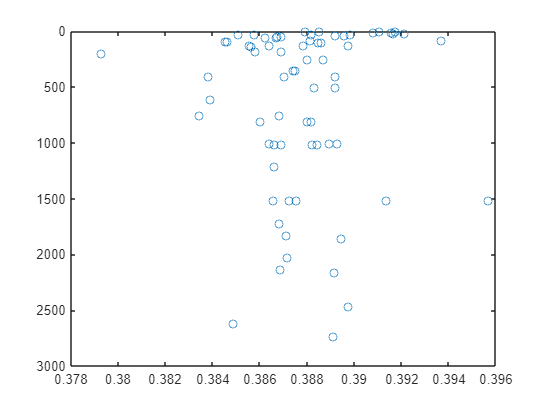

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

btlsum0.CTDoxy_mLL_cal = btlsum0.CTDoxy_mLL; % Because don't have cal product

[cal] = E2_calculation(btlsum0,cal,CTD_sen1); % Use dummy bottle summary with outlier removed

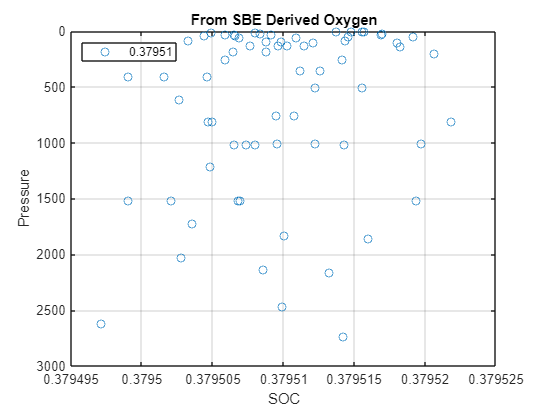

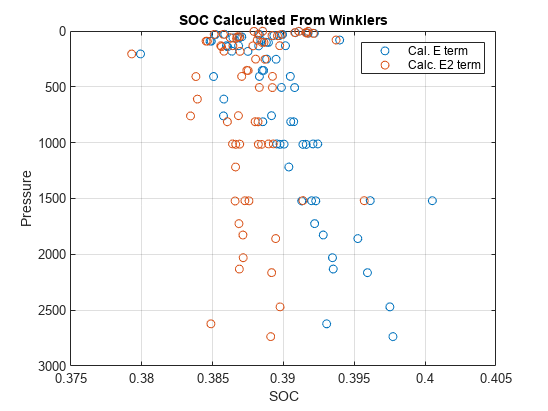

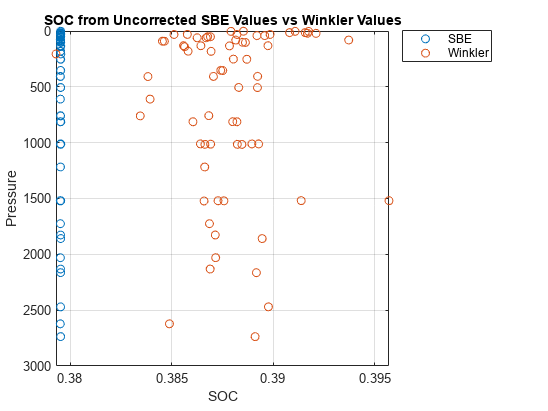

New SOC = 0.38784
EGain = 1.0219+/- 0.0066052



[cal] = Gain_E2_Calculation(btlsum0,cal,CTD_sen1); % Use dummy bottle summary with any outliers removed

% Read in processed casts
% Processed with 4 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')
cast01u = readSBScnv( 'uar0701001.cnv' );
cast02u = readSBScnv( 'uar0701002.cnv' );
cast03u = readSBScnv( 'uar0701003.cnv' );
cast04u = readSBScnv( 'uar0701004.cnv' );
cast05u = readSBScnv( 'uar0701005.cnv' );
cast06u = readSBScnv( 'uar0701006.cnv' );
cast07u = readSBScnv( 'uar0701007.cnv' );
cast08u = readSBScnv( 'uar0701008.cnv' );
cast09u = readSBScnv( 'uar0701009.cnv' );
cast10u = readSBScnv( 'uar0701010.cnv' );

cast01d = readSBScnv( 'dar0701001.cnv' );
cast02d = readSBScnv( 'dar0701002.cnv' );
cast03d = readSBScnv( 'dar0701003.cnv' );
cast04d = readSBScnv( 'dar0701004.cnv' );
cast05d = readSBScnv( 'dar0701005.cnv' );
cast06d = readSBScnv( 'dar0701006.cnv' );
cast07d = readSBScnv( 'dar0701007.cnv' );
cast08d = readSBScnv( 'dar0701008.cnv' );
cast09d = readSBScnv( 'dar0701009.cnv' );
cast10d = readSBScnv( 'dar0701010.cnv' );

% % Format to table without Leah's product 
% [cast01u, cast01u0] = combine_CTD_files_woutCTDcal(cast01u); [cast01d, cast01d0] = combine_CTD_files_woutCTDcal(cast01d);  
% [cast02u, cast02u0] = combine_CTD_files_woutCTDcal(cast02u); [cast02d, cast02d0] = combine_CTD_files_woutCTDcal(cast02d);  
% [cast03u, cast03u0] = combine_CTD_files_woutCTDcal(cast03u); [cast03d, cast03d0] = combine_CTD_files_woutCTDcal(cast03d);  
% [cast04u, cast04u0] = combine_CTD_files_woutCTDcal(cast04u); [cast04d, cast04d0] = combine_CTD_files_woutCTDcal(cast04d);  
% [cast05u, cast05u0] = combine_CTD_files_woutCTDcal(cast05u); [cast05d, cast05d0] = combine_CTD_files_woutCTDcal(cast05d);  
% [cast06u, cast06u0] = combine_CTD_files_woutCTDcal(cast06u); [cast06d, cast06d0] = combine_CTD_files_woutCTDcal(cast06d);  
% [cast07u, cast07u0] = combine_CTD_files_woutCTDcal(cast07u); [cast07d, cast07d0] = combine_CTD_files_woutCTDcal(cast07d);  
% [cast08u, cast08u0] = combine_CTD_files_woutCTDcal(cast08u); [cast08d, cast08d0] = combine_CTD_files_woutCTDcal(cast08d);  
% [cast09u, cast09u0] = combine_CTD_files_woutCTDcal(cast09u); [cast09d, cast09d0] = combine_CTD_files_woutCTDcal(cast09d);  
% [cast10u, cast10u0] = combine_CTD_files_woutCTDcal(cast10u); [cast10d, cast10d0] = combine_CTD_files_woutCTDcal(cast10d); 

% Format to table without Leah's product 
[cast01u, ~] = combine_CTD_files_woutCTDcal(cast01u); [cast01d, ~] = combine_CTD_files_woutCTDcal(cast01d);  
[cast02u, ~] = combine_CTD_files_woutCTDcal(cast02u); [cast02d, ~] = combine_CTD_files_woutCTDcal(cast02d);  
[cast03u, ~] = combine_CTD_files_woutCTDcal(cast03u); [cast03d, ~] = combine_CTD_files_woutCTDcal(cast03d);  
[cast04u, ~] = combine_CTD_files_woutCTDcal(cast04u); [cast04d, ~] = combine_CTD_files_woutCTDcal(cast04d);  
[cast05u, ~] = combine_CTD_files_woutCTDcal(cast05u); [cast05d, ~] = combine_CTD_files_woutCTDcal(cast05d);  
[cast06u, ~] = combine_CTD_files_woutCTDcal(cast06u); [cast06d, ~] = combine_CTD_files_woutCTDcal(cast06d);  
[cast07u, ~] = combine_CTD_files_woutCTDcal(cast07u); [cast07d, ~] = combine_CTD_files_woutCTDcal(cast07d);  
[cast08u, ~] = combine_CTD_files_woutCTDcal(cast08u); [cast08d, ~] = combine_CTD_files_woutCTDcal(cast08d);  
[cast09u, ~] = combine_CTD_files_woutCTDcal(cast09u); [cast09d, ~] = combine_CTD_files_woutCTDcal(cast09d);  
[cast10u, ~] = combine_CTD_files_woutCTDcal(cast10u); [cast10d, ~] = combine_CTD_files_woutCTDcal(cast10d); 


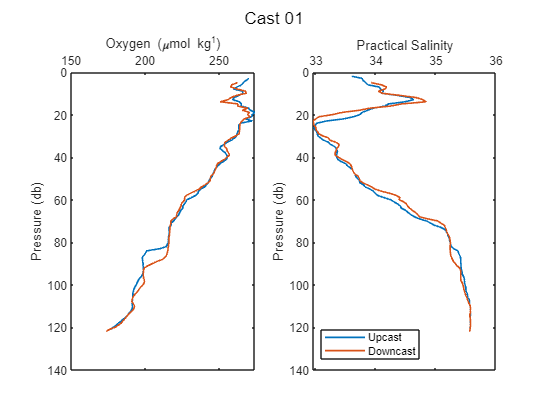

% Using function written for missing final Sal product 
sal_plots = 1; leah_plot = 0; 
% [castu, castd, btlsum] = Process_Cast_Gain_E2_woutCTDcal(castu,castd,cal,btlsum,sal_plots,leah_plots,CTD_sen,CastString)

[cast01u, cast01d, btlsum01] = Process_Cast_Gain_E2_woutCTDcal(cast01u,cast01d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 01');

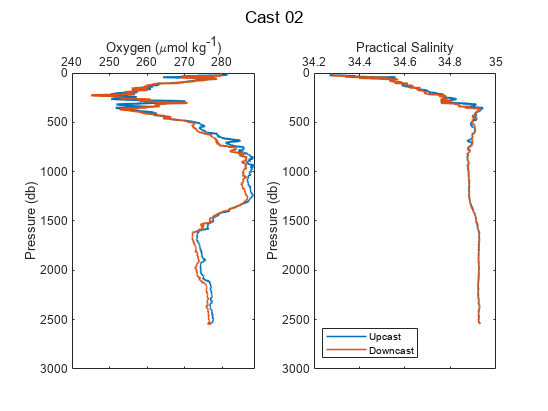

[cast02u, cast02d, btlsum02] = Process_Cast_Gain_E2_woutCTDcal(cast02u,cast02d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 02');

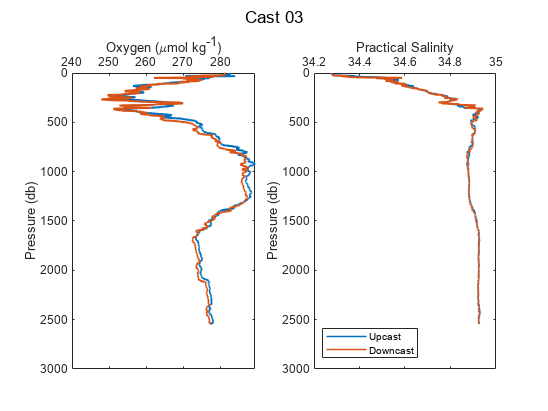

[cast03u, cast03d, btlsum03] = Process_Cast_Gain_E2_woutCTDcal(cast03u,cast03d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 03');

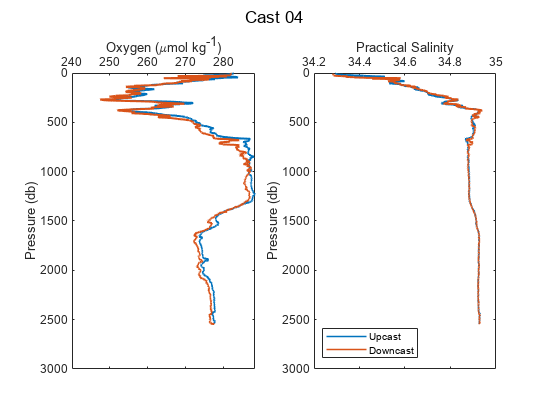

[cast04u, cast04d, btlsum04] = Process_Cast_Gain_E2_woutCTDcal(cast04u,cast04d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 04');

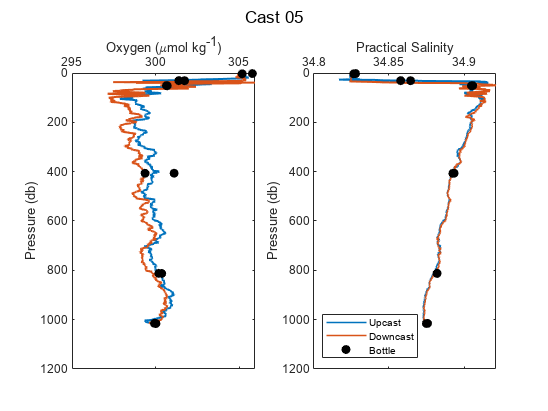

[cast05u, cast05d, btlsum05] = Process_Cast_Gain_E2_woutCTDcal(cast05u,cast05d,cal,btlsum05,sal_plots,leah_plot,CTD_sen1,'Cast 05');

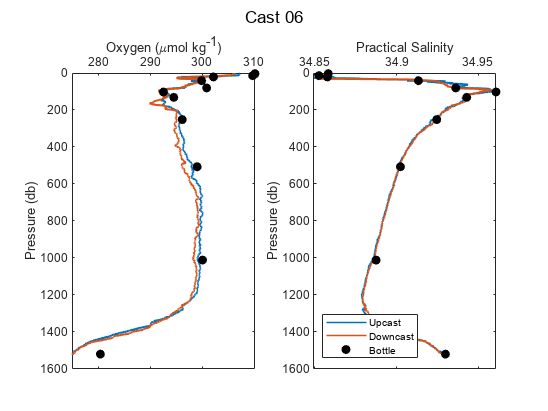

[cast06u, cast06d, btlsum06] = Process_Cast_Gain_E2_woutCTDcal(cast06u,cast06d,cal,btlsum06,sal_plots,leah_plot,CTD_sen1,'Cast 06');

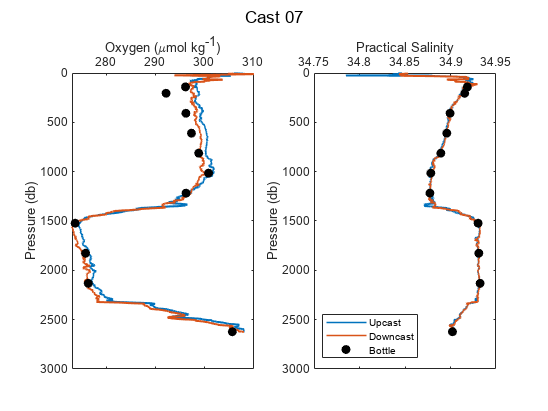

[cast07u, cast07d, btlsum07] = Process_Cast_Gain_E2_woutCTDcal(cast07u,cast07d,cal,btlsum07,sal_plots,leah_plot,CTD_sen1,'Cast 07');

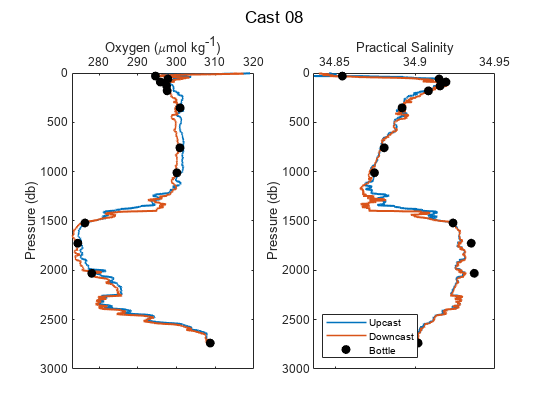

[cast08u, cast08d, btlsum08] = Process_Cast_Gain_E2_woutCTDcal(cast08u,cast08d,cal,btlsum08,sal_plots,leah_plot,CTD_sen1,'Cast 08');

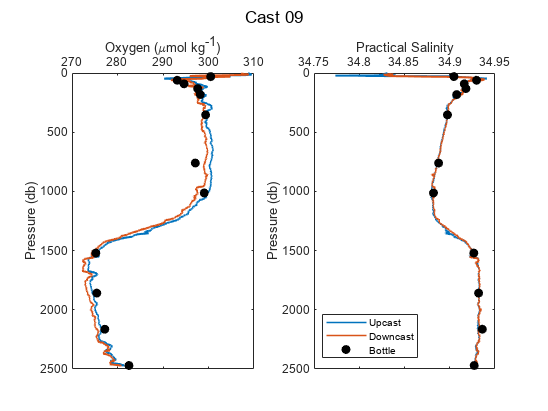

[cast09u, cast09d, btlsum09] = Process_Cast_Gain_E2_woutCTDcal(cast09u,cast09d,cal,btlsum09,sal_plots,leah_plot,CTD_sen1,'Cast 09');

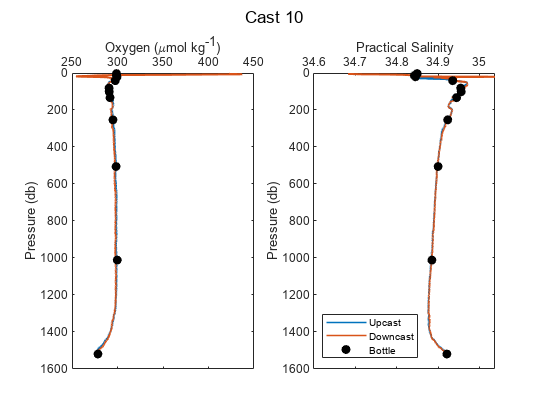

[cast10u, cast10d, btlsum10] = Process_Cast_Gain_E2_woutCTDcal(cast10u,cast10d,cal,btlsum10,sal_plots,leah_plot,CTD_sen1,'Cast 10');

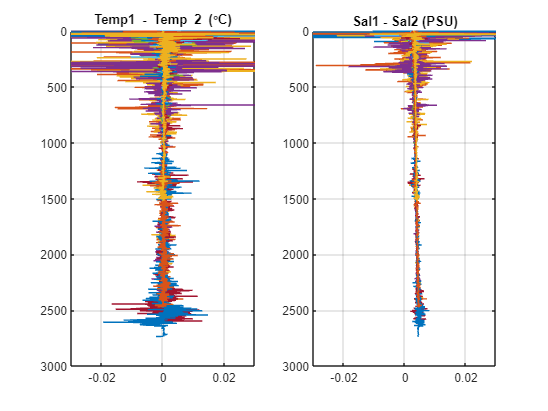

figure
subplot(1,2,1)
plot(cast01u.temp1-cast01u.temp2,cast01u.prs)
hold on
plot(cast02u.temp1-cast02u.temp2,cast02u.prs)
plot(cast03u.temp1-cast03u.temp2,cast03u.prs)
plot(cast04u.temp1-cast04u.temp2,cast04u.prs)
plot(cast05u.temp1-cast05u.temp2,cast05u.prs)
plot(cast06u.temp1-cast06u.temp2,cast06u.prs)
plot(cast07u.temp1-cast07u.temp2,cast07u.prs)
plot(cast08u.temp1-cast08u.temp2,cast08u.prs)
plot(cast09u.temp1-cast09u.temp2,cast09u.prs)
plot(cast10u.temp1-cast10u.temp2,cast10u.prs)
axis ij
grid on
xlim([-0.03 0.03])
title('Temp1 - Temp 2 (\circC)')

subplot(1,2,2)
plot(cast01u.sal1-cast01u.sal2,cast01u.prs)
hold on
plot(cast02u.sal1-cast02u.sal2,cast02u.prs)
plot(cast03u.sal1-cast03u.sal2,cast03u.prs)
plot(cast04u.sal1-cast04u.sal2,cast04u.prs)
plot(cast05u.sal1-cast05u.sal2,cast05u.prs)
plot(cast06u.sal1-cast06u.sal2,cast06u.prs)
plot(cast07u.sal1-cast07u.sal2,cast07u.prs)
plot(cast08u.sal1-cast08u.sal2,cast08u.prs)
plot(cast09u.sal1-cast09u.sal2,cast09u.prs)
plot(cast10u.sal1-cast10u.sal2,cast10u.prs)
axis ij
grid on
xlim([-0.03 0.03])
title('Sal1 - Sal2 (PSU)')

btlsum_yr3 = [btlsum05; btlsum06; btlsum07; btlsum08; btlsum09; btlsum10];
btlsum_yr3_OOI = [btlsum05; btlsum06; btlsum07; btlsum08; btlsum09; btlsum10];

disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 4


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term (E2) = ' num2str(cal.E2)])

Adjust. E term (E2) = 0.0382


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.37951


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.38784


disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])

E2Gain = 1.0219+/- 0.0066052


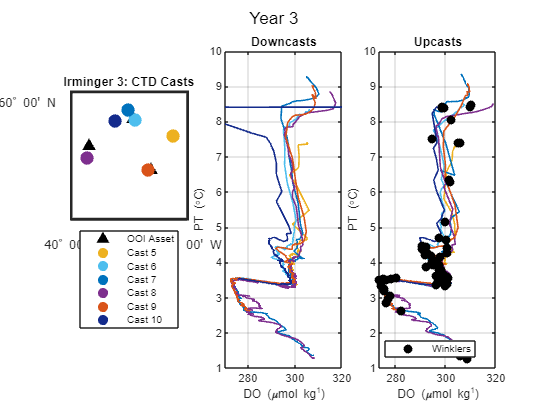

run('Year3_PT_DO_plots.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')
clear btlsum0 btl
dt_Processed = datetime;
save Year3_Processed_KF cast* btl* cal* dt_Processed 